% Parámetros DH (estándar) de PhantomX Pincher
links(1) = Link('d', 0.046,    'a', 0,         'alpha', pi/2, 'qlim', [-180 180]);
links(2) = Link('d', 0,        'a', 0.107,     'alpha', 0,    'qlim', [0 180]);
links(3) = Link('d', 0,        'a', 0.107,    'alpha', 0,    'qlim', [-100 100]);
links(4) = Link('d', 0,        'a', 0.066,  'alpha', 0,    'qlim', [-160 160]);

arm = SerialLink(links, 'name', 'PX_Pincher');

arm.base = transl(0, 0, 0.05);

disp('El modelo del robot ha sido generado y almacenado en la variable arm.');

El modelo del robot ha sido generado y almacenado en la variable arm.


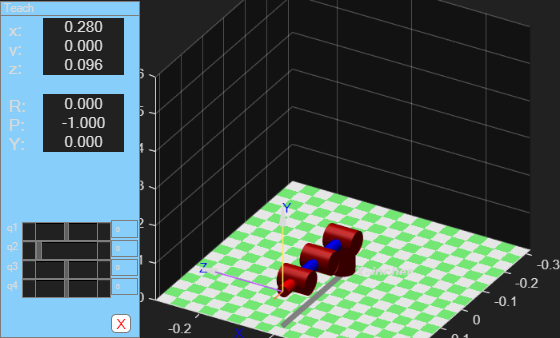


q_init = zeros(1, arm.n);

figure('Name','Vista del robot PX Pincher');
arm.plot(q_init, ...
    'workspace', [-0.3 0.3 -0.3 0.3 0 0.6], ...
    'scale', 1.0, ...
    'view', [120 30], ...
    'tilesize', 0.04, ...
    'floorlevel', 0);

title('Visualización del Manipulador PX');

arm.teach;